# Slice Plot for Generalized Linear Regression Model

Plot slices through a fitted generalized linear regression model surface.

Generate sample data using Poisson random numbers with two underlying predictors `X(:,1)` and `X(:,2)`.

rng('default') % For reproducibility
rndvars = randn(100,2);
X = [2 + rndvars(:,1),rndvars(:,2)];
mu = exp(1 + X*[1;2]);
y = poissrnd(mu);

Create a generalized linear regression model of Poisson data.

mdl = fitglm(X,y,'y ~ x1 + x2','Distribution','poisson');

Create a slice plot.

plotSlice(mdl)

The green line in each plot represents the predicted response values as a function of a single predictor variable, with the other predictor variables held constant. The red dotted lines are the 95% confidence bounds. The *y*-axis label includes the predicted response value and the corresponding confidence bound for the point selected by the vertical and horizontal lines. The *x*-axis label shows the predictor variable name and the predictor value for the selected point.

Move the vertical line in the `x1` plot to the right and observe the change in the *y*-axis label and the changes in the `x2` plot.

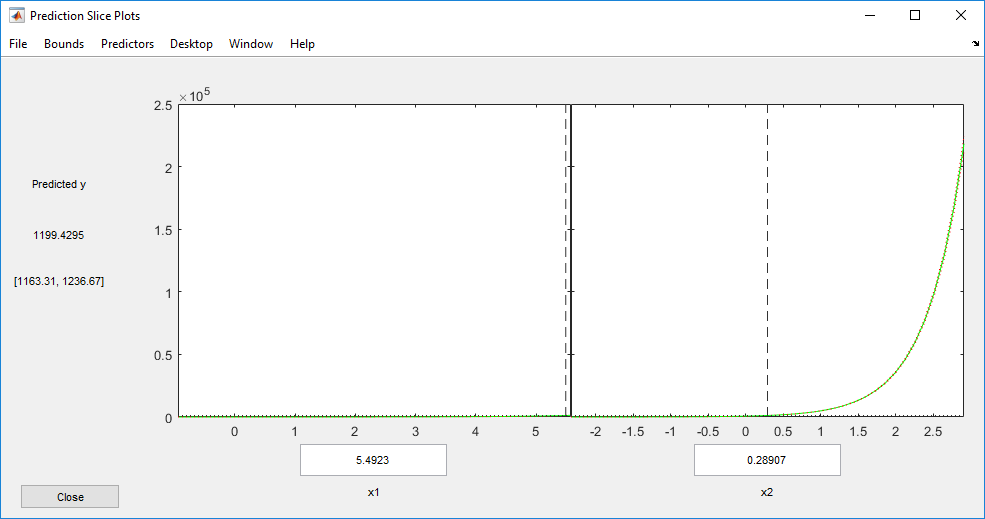

*Copyright 2018 The MathWorks, Inc.*